Polynomial equation with interactions terms

quadraticfun1 = @(b,p)( ...
    +b(1).*p1 ...  
    +b(2).*p2 ...
    +b(3).*p3 ...
    +b(4).*p4 ...
    +b(5).*p1.*p1 ...
    +b(6).*p2.*p2 ...
    +b(7).*p3.*p3 ...
    +b(8).*p4.*p4 ...
    +b(9).*p1.*p2 ...
    +b(10).*p1.*p3 ...
    +b(11).*p1.*p4 ...
    +b(12).*p2.*p3 ...
    +b(13).*p2.*p4 ...
    +b(14).*p3.*p4 ...
    +b(15) ...
    );


p must be a matrix. if multiple variable are included, do not use multiple vectors but a matrix.

beta0 = ones(15,1) %%% initial coefficient value %%%%
b = nlinfit(p,t1,quadraticfun1,beta0)

Polynomial equation with interactions terms

quadraticfun1 = @(c,p)( ...
    +c(1).*p1 ...  
    +c(2).*p2 ...
    +c(3).*p3 ...
    +c(4).*p4 ...
    +c(5).*p1.*p1 ...
    +c(6).*p2.*p2 ...
    +c(7).*p3.*p3 ...
    +c(8).*p4.*p4 ...
    +c(9).*p1.*p2 ...
    +c(10).*p1.*p3 ...
    +c(11).*p1.*p4 ...
    +c(12).*p2.*p3 ...
    +c(13).*p2.*p4 ...
    +c(14).*p3.*p4 ...
    +c(15) ...
    );


p must be a matrix. if multiple variable are included, do not use multiple vectors but a matrix.

beta0 = ones(15,1) %%% initial coefficient value %%%%
c = nlinfit(p,t2,quadraticfun1,beta0)

[j,k]=meshgrid(1:0.02:2,120:0.8:160)
[u,v]=meshgrid(300:4:500,2:0.06:5)
x1 = j;
x2 = k;
x3 = u;
x4 = v;


responsesurf1 = ( ...
    +b(1).*x1 ...  
    +b(2).*x2 ...
    +b(3).*x3 ...
    +b(4).*x4 ...
    +b(5).*x1.*x1 ...
    +b(6).*x2.*x2 ...
    +b(7).*x3.*x3 ...
    +b(8).*x4.*x4 ...
    +b(9).*x1.*x2 ...
    +b(10).*x1.*x3 ...
    +b(11).*x1.*x4 ...
    +b(12).*x2.*x3 ...
    +b(13).*x2.*x4 ...
    +b(14).*x3.*x4 ...
    +b(15) ...
    );

responsesurf2 = ( ...
    +c(1).*x1 ...  
    +c(2).*x2 ...
    +c(3).*x3 ...
    +c(4).*x4 ...
    +c(5).*x1.*x1 ...
    +c(6).*x2.*x2 ...
    +c(7).*x3.*x3 ...
    +c(8).*x4.*x4 ...
    +c(9).*x1.*x2 ...
    +c(10).*x1.*x3 ...
    +c(11).*x1.*x4 ...
    +c(12).*x2.*x3 ...
    +c(13).*x2.*x4 ...
    +c(14).*x3.*x4 ...
    +c(15) ...
    );



[w,x]=meshgrid(0:0.02:1,0:0.02:1)
[y,z]=meshgrid(0:0.02:1,0:0.02:1)
ipfpred=zeros(51)
for row=1:51
    for column=1:51
        predinput=[w(row,column);x(row,column);y(row,column);z(row,column)]
        pred = poslin(predinput);
        ipfpred(row,column) = pred(1,1);
        seapred(row,column) = pred(2,1);
    end
end
ANNIPF = ((ipfpred)*(max(data(:,5))-min(data(:,5))))+min(data(:,5))
ANNSEA = ((seapred)*(max(data(:,6))-min(data(:,6))))+min(data(:,6))

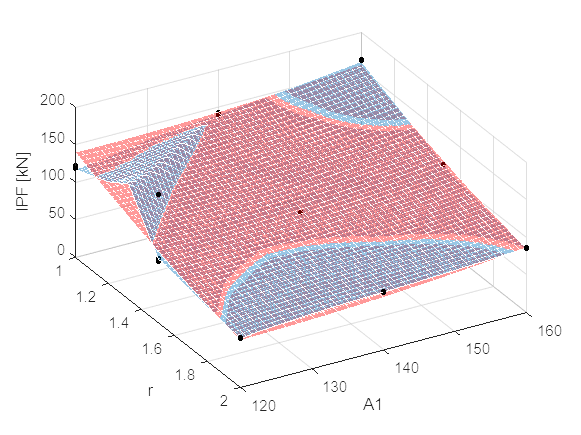

mesh(j,k,responsesurf1,'FaceAlpha',0.4,'EdgeColor','#FFFFFF','FaceColor','r');
xlabel('r');
ylabel('A1')
zlabel('IPF [kN]')
view(60,45)
hold on;
mesh(j,k,ANNIPF,'FaceAlpha',0.4,'EdgeColor','#FFFFFF','FaceColor','#0072BD');
plot3(p1,p2,t1,'k.','MarkerSize',10);
hold off;
zlim([0 200])

mesh(j,k,responsesurf2,'FaceAlpha',0.4,'EdgeColor','#FFFFFF','FaceColor','r');
view(60,45)
hold on;

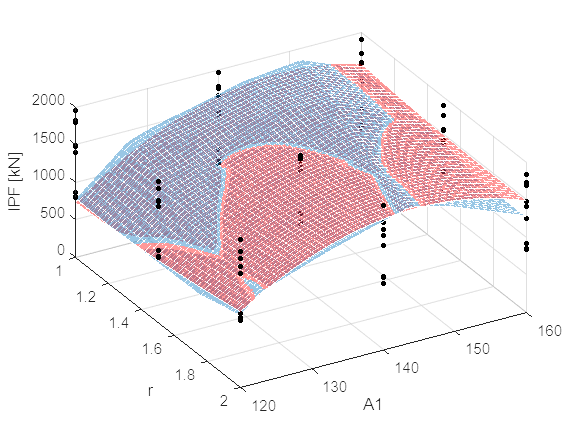

mesh(j,k,ANNSEA,'FaceAlpha',0.4,'EdgeColor','#FFFFFF','FaceColor','#0072BD');
plot3(p1,p2,t2,'k.','MarkerSize',10);
hold off;
zlim([0 2000])
xlabel('r');
ylabel('A1')
zlabel('IPF [kN]')